Setup and function calls

clc;
clear;
close all;

k1 = 4.66;
k2 = 4.66;
m1 = 0.0917;
m2 = 0.0765;

A = [0, 1, 0, 0;
    -1*(k1+k2)/m1, 0, k2/m1, 0;
    0, 0, 0, 1;
    k2/m2, 0, -1*k2/m2, 0];

disp(eig(A));

   0.0000 +11.8542i
   0.0000 -11.8542i
   0.0000 + 4.6935i
   0.0000 - 4.6935i



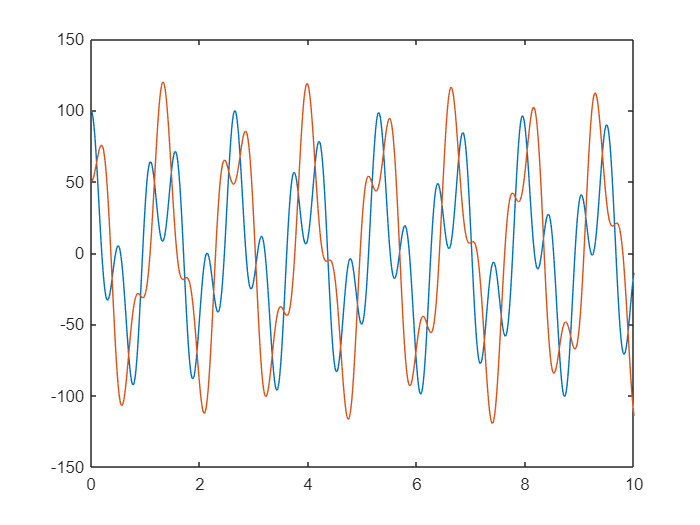


x1p0 = 0;
x2p0 = 0;

x10 = 100;
x20 = 50;

T = 10;
N = 1000;

[t, x1, x1p, x2, x2p] = IEMsolver(A, x10, x1p0, x20, x2p0, T, N);

figure;
plot(t, x1);
hold on;
plot(t, x2);

IEMsolver function

function [t, x1, x1p, x2, x2p] = IEMsolver(A, x10, x1p0, x20, x2p0, T, N)
    dt = T/N;
    t = 0:dt:T;

    SOL = NaN(4, length(t));
    SOL(1,1) = x10;
    SOL(2,1) = x1p0;
    SOL(3,1) = x20;
    SOL(4,1) = x2p0;

    for k = 2:length(t)
        zn = SOL(:,k-1);
        SL = A * zn;
        SR = A * (zn + dt * A * zn);
        SOL(:,k) = zn + (dt / 2) * (SL + SR);
    end

    x1 = SOL(1,:);
    x1p = SOL(2,:);
    x2 = SOL(3,:);
    x2p = SOL(4,:);
end